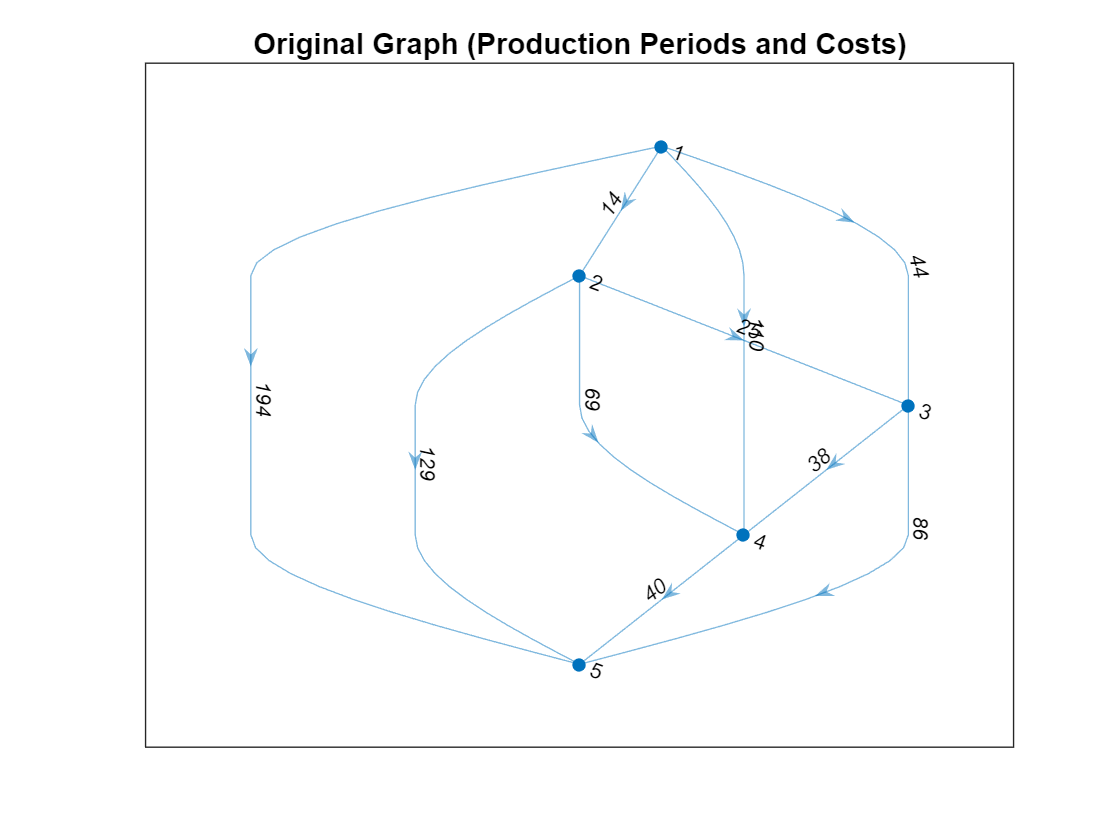

Optimal Production Plan:
Minimum Cost: 80.000000
Minimum Cost: 117.000000
Predecessors:      0     1     2     3     4

Production should occur in periods:      2
     3
     4
     5



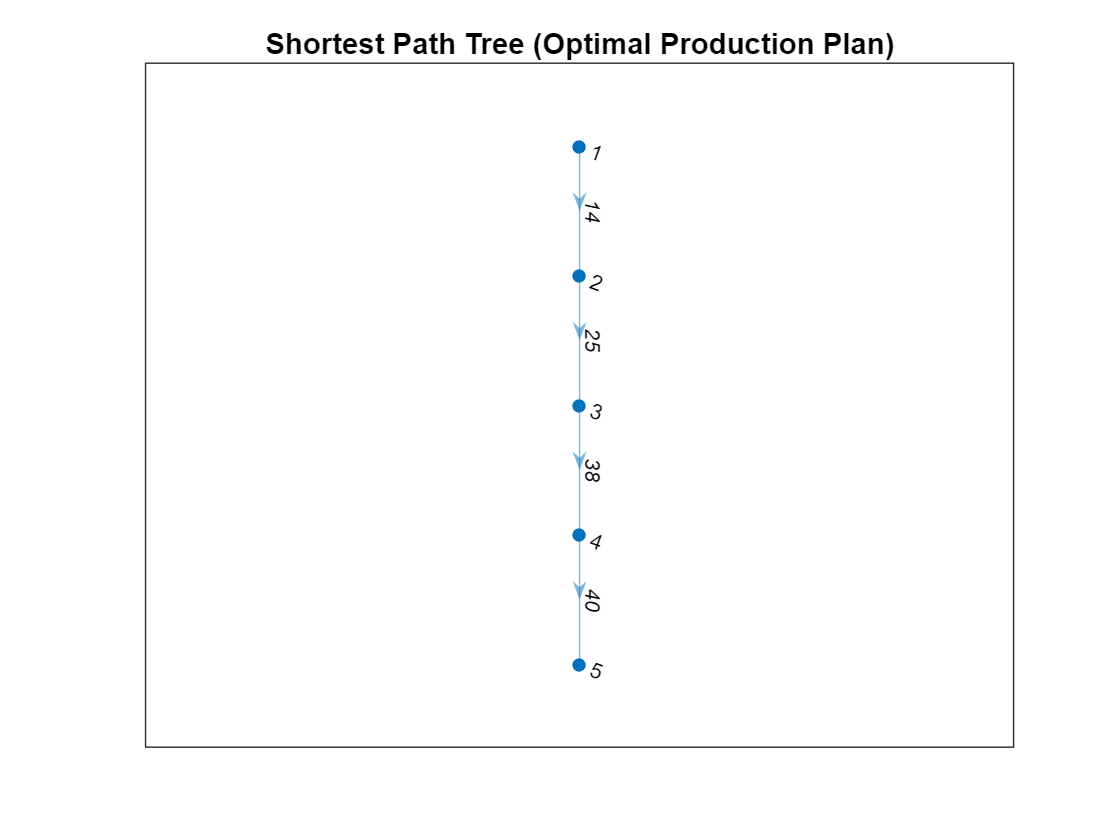

filename = 'test.txt';

solveLotSizing(filename);


% b) Construct the graph from file

function graph = constructGraphFromFile(filename)
    % Read the input data from the file
    [n, demand, setup_cost, unit_cost, storage_cost] = readInputFile(filename);
    
    % Initialize the graph with n + 1 nodes (1 to n+1)
    graph = digraph();
    
    % Iterate through time periods to set up edges (use 1-based index)
    for i = 1:n
        for j = i+1:n+1
            % Calculate the cost of edge (i, j)
            total_production_cost = calculateCost(i-1, j-1, demand, setup_cost, unit_cost, storage_cost);
            graph = addedge(graph, i, j, total_production_cost);
        end
    end
    
    % Plot the original graph
    figure;
    plot(graph, 'EdgeLabel', graph.Edges.Weight);
    title('Original Graph (Production Periods and Costs)');
end

% Calculate cost between two time periods
function cost = calculateCost(i, j, demand, setup_cost, unit_cost, storage_cost)
    % Calculate the cost of producing in period i and covering demands up to period j
    % i is the start period, j is the end period
    production_cost = sum(demand(i+1:j) .* unit_cost(i+1));  % Produce once, use unit cost from period i
    setup_cost = setup_cost(i+1);  % Setup cost is only charged once, in the start period
    
    % Calculate storage costs for holding inventory for future periods
    storage_cost_total = 0;
    for k = i+1:j-1
        % Storage cost for demand in period k stored until period j
        storage_cost_total = storage_cost_total + sum(demand(k+1:j) .* storage_cost(k+1));
    end
    
    % Total cost is the sum of setup, production, and storage costs
    cost = setup_cost + production_cost + storage_cost_total;
end

% Read input from file
function [n, demand, setup_cost, unit_cost, storage_cost] = readInputFile(filename)
    % Open the file
    fid = fopen(filename, 'r');
    
    % Read the number of time periods (n)
    n = fscanf(fid, '%d', 1);
    
    % Initialize arrays
    demand = zeros(n, 1);
    setup_cost = zeros(n, 1);
    unit_cost = zeros(n, 1);
    storage_cost = zeros(n, 1);
    
    % Read the data for each time period
    for i = 1:n
        data = fscanf(fid, '%d %d %d %d', [1, 4]);
        demand(i) = data(1);
        setup_cost(i) = data(2);
        unit_cost(i) = data(3);
        storage_cost(i) = data(4);
    end
    
    % Close the file
    fclose(fid);
end

% c) Solve lot sizing problem
function solveLotSizing(filename)
    % Construct the graph from the input file
    G = constructGraphFromFile(filename);
    
    % Number of time periods
    [n, ~, ~, ~, ~] = readInputFile(filename);
    
    % Solve the shortest path from node 1 to node n+1 using Bellman-Ford
    [dist, pred] = BellmanFordPWSSSP(n+1, G.Edges.EndNodes, G.Edges.Weight, 1);

    % Output the solution: Time periods and production amounts
    disp('Optimal Production Plan:');
    dispSolution(dist, pred, n);
    
    % Plot the shortest path tree
    plotShortestPathTree(G, pred, n+1);
end

% Display the solution
function dispSolution(dist, pred, n)
    % Display the shortest path result
    fprintf('Minimum Cost: %f\n', dist(n+1));
    fprintf('Predecessors: ');
    disp(pred');
    
    % Display the production plan
    periods = find(pred > 0);  % Find periods where production happens
    fprintf('Production should occur in periods: ');
    disp(periods);
end

% Plot the shortest path tree
function plotShortestPathTree(G, pred, V)
    % Initialize arrays to store the edges in the shortest path tree
    treeEdges = [];
    treeWeights = [];
    
    % Reconstruct the shortest path tree based on the predecessor array
    for v = 2:V
        if pred(v) ~= 0  % If v has a predecessor, it's part of the tree
            treeEdges = [treeEdges; pred(v), v];
            % Find the corresponding weight of the edge in the original graph
            idx = find(G.Edges.EndNodes(:,1) == pred(v) & G.Edges.EndNodes(:,2) == v);
            treeWeights = [treeWeights; G.Edges.Weight(idx)];
        end
    end
    
    % Create a new graph for the shortest path tree
    treeGraph = digraph(treeEdges(:,1), treeEdges(:,2), treeWeights);
    
    % Plot the shortest path tree
    figure;
    plot(treeGraph, 'EdgeLabel', treeGraph.Edges.Weight);
    title('Shortest Path Tree (Optimal Production Plan)');
end

% Bellman-Ford function (from Lab2)
function [dist, pred] = BellmanFordPWSSSP(V, edgeList, weights, s)
    % Initialize distance and predecessor arrays
    dist = ones(V, 1) * Inf;  % Initialize all distances as infinity
    pred = zeros(V, 1);       % Initialize predecessors as 0 (or -1 for unvisited nodes)
    
    dist(s) = 0;  % Distance from source to itself is 0
    
    % Bellman-Ford main algorithm loop
    for i = 1:V-1
        for j = 1:length(edgeList)
            u = edgeList(j, 1);
            v = edgeList(j, 2);
            w = weights(j);
            if dist(u) + w < dist(v)  % Relax the edge
                dist(v) = dist(u) + w;
                pred(v) = u;  % Record predecessor
            end
        end
    end
end
